Daniel Sklyar

Homework #3

Exercise 2

a)

    Newtons_method function the function block below

b)

f = @(x) atan(x)-1; % arctan(x) = 1 -> arctan(x) - 1 = 0
fp = @(x) 1./(1 + x.^(2));
tol = 10.^(-8);

i)

initial_guess = 2;
[c,n,err] = newtons_method(f,fp,initial_guess,tol,100);
fprintf('Calculated solution: %d\n',c(end));

Calculated solution: 1.557408e+00


fprintf('Iteration taken: %d\n',n);

Iteration taken: 5


fprintf('Last iteration error: %d\n',err(end-1));

Last iteration error: 6.901598e-06


    My newton's method converged after 5 iteration at the correct solution of x = 1.5574. 

    Last iteration's  error =  6.9*10^(-6)

ii)

initial_guess = -2;
[c,n,err] = newtons_method(f,fp,initial_guess,tol,100);
fprintf('Calculated solution: %d\n',c(end));

Calculated solution: NaN


fprintf('Iteration taken: %d\n',n);

Iteration taken: 11


fprintf('Last iteration error: %d\n',err(end-1));

Last iteration error: Inf


    My newton's method did not converged after 11 iteration. I think it diverged.

    The reason for break in loop was because the logic was unable to evaluate variable [err]

    Last iteration's  error =  infinity

c)

initial_guess = 2;
[c,n,err] = newtons_method(f,fp,initial_guess,tol,100);
xp = -5:1:5;
plot(xp,atan(xp)-1);
hold on;
first_three_iterations = c(1:3) % first 3 elements

first_three_iterations =     1.4643    1.5535    1.5574


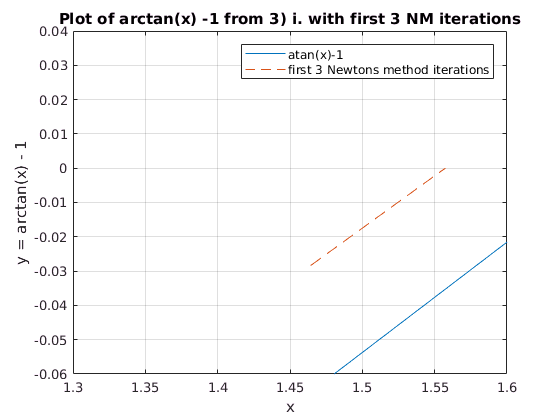

title('Plot of arctan(x) -1 from 3) i. with first 3 NM iterations');
plot(first_three_iterations,f(first_three_iterations),'--');
legend('atan(x)-1','first 3 Newtons method iterations');
ylabel('y = arctan(x) - 1');
xlabel('x');
grid on;
%COOMENT THESE 2 IF YOU WANT TO SEE THE WHOLE PLOT!!!!
xlim([1.3 1.6]);
ylim([-0.06 0.04]);
hold off;

Exercise 3

a)

    Lagrange_poly function is in the function block

b)

i)

disp('PART B) i. y = e^(-x^(2))');

PART B) i. y = e^(-x^(2))


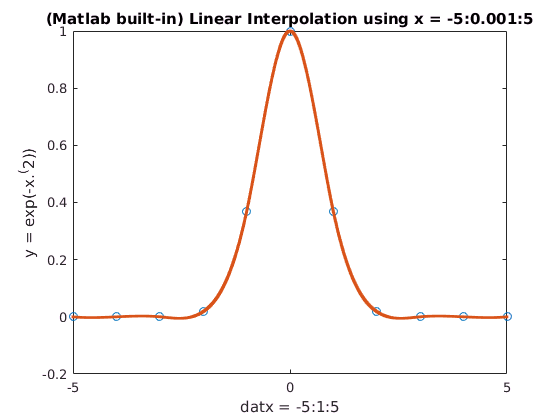

datx = -5:1:5;
x = -5:0.001:5;
daty =  exp(-datx.^(2));

test = interp1(datx,daty,x,'spline');
plot(datx,daty,'o',x,test,':.');
title('(Matlab built-in) Linear Interpolation using x = -5:0.001:5');
ylabel('y = exp(-x.^(2))');
xlabel('datx = -5:1:5');
hold off;

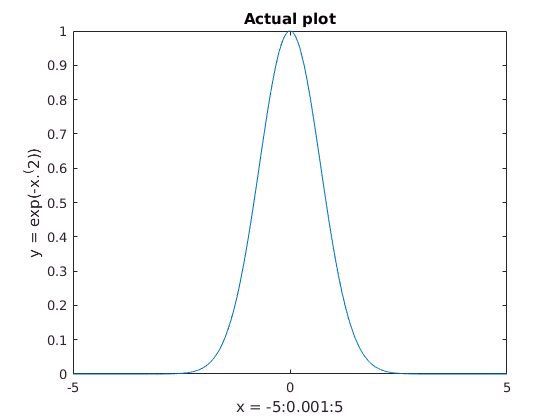


plot(x,exp(-x.^(2)));
title('Actual plot');
ylabel('y = exp(-x.^(2))');
xlabel('x = -5:0.001:5');
hold off;

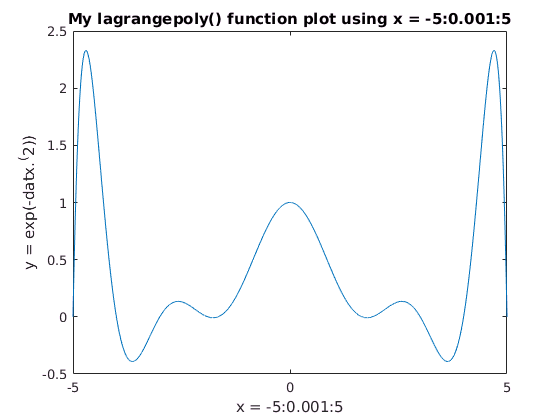


y = lagrange_poly(x,datx,daty);
plot(x,y);
title('My lagrangepoly() function plot using x = -5:0.001:5');
ylabel('y = exp(-datx.^(2))');
xlabel('x = -5:0.001:5');
hold off;

    The error increased as closer it got to the -5:15 boundaries. hence the large maximas in the both ends

    of graph bounds.

ii)

disp('PART B) ii. y = 1/(1+x^(2))');

PART B) ii. y = 1/(1+x^(2))


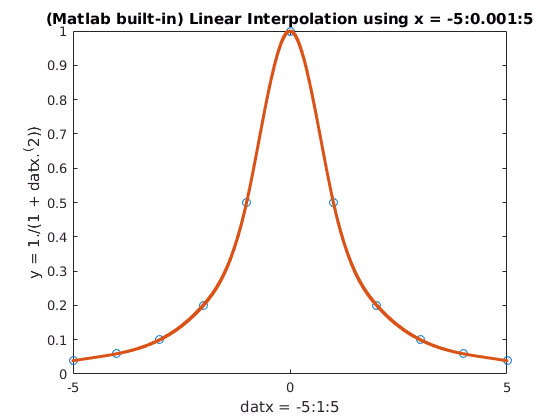

datx = -5:1:5;
x = -5:0.001:5;
daty =  1./(1 + datx.^(2));

test = interp1(datx,daty,x,'spline');
plot(datx,daty,'o',x,test,':.');
title('(Matlab built-in) Linear Interpolation using x = -5:0.001:5');
ylabel('y = 1./(1 + datx.^(2))');
xlabel('datx = -5:1:5');
hold off;

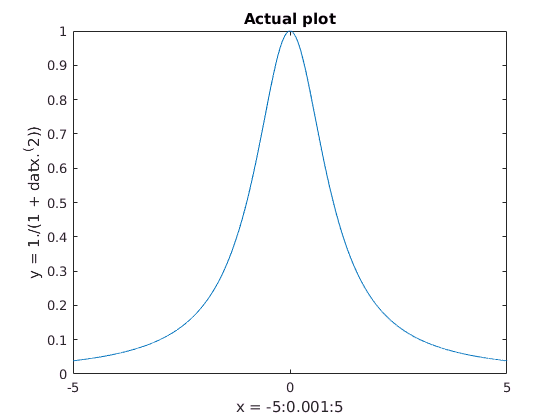


plot(x,1./(1 + x.^(2)));
title('Actual plot');
ylabel('y = 1./(1 + datx.^(2))');
xlabel('x = -5:0.001:5');
hold off;

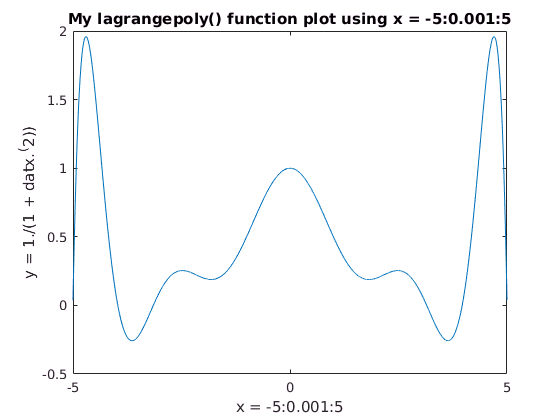


y = lagrange_poly(x,datx,daty);
plot(x,y);
title('My lagrangepoly() function plot using x = -5:0.001:5');
ylabel('y = 1./(1 + datx.^(2))');
xlabel('x = -5:0.001:5');
hold off;

    Same as last one, he error increased as closer it got to the -5:15 boundaries. hence the large maximas in 

    the both ends  of graph bounds.

c)

i)

disp('PART C) i. y = e^(-x^(2))');

PART C) i. y = e^(-x^(2))


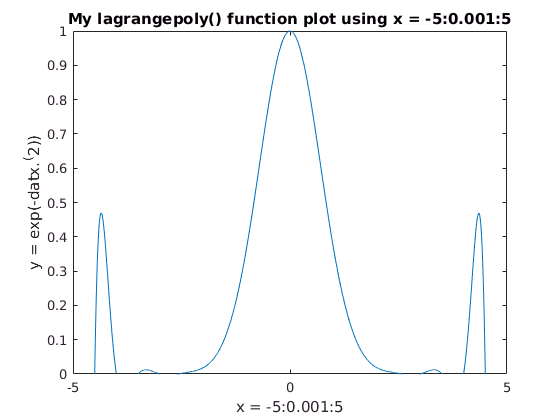

datx = -5:0.5:5;
x = -5:0.001:5;
daty =  exp(-datx.^(2));

y = lagrange_poly(x,datx,daty);
plot(x,y);
title('My lagrangepoly() function plot using x = -5:0.001:5');
ylabel('y = exp(-datx.^(2))');
xlabel('x = -5:0.001:5');
ylim([0 1]);
hold off;

    This interpolation is a bit better, but it still has major erros as function approaches -5:1:5 boundaries. There are

    two large minimas near the plot boundaries and two local maximas .

ii)

disp('PART C) ii. y = 1/(1+x^(2))');

PART C) ii. y = 1/(1+x^(2))


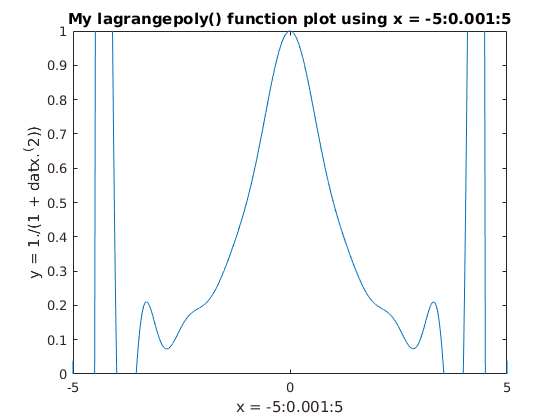

datx = -5:0.5:5;
x = -5:0.001:5;
daty =  1./(1 + datx.^(2));

y = lagrange_poly(x,datx,daty);
plot(x,y);
title('My lagrangepoly() function plot using x = -5:0.001:5');
ylabel('y = 1./(1 + datx.^(2))');
xlabel('x = -5:0.001:5');
ylim([0 1]);
hold off;

    Same as above, this interpolation is a bit better, but it still has major erros as function approaches -5:1:5         

    boundaries. There are two large minimas near the plot boundaries and two large maximas .

function [c,n,err] = newtons_method(f,fp,x0,tol,N)
    n = 1;                        % set n = 1 as first iteration is calc below
    c = [];                       % set c list as empty
    c(n) = x0 - f(x0)./fp(x0);    % calculate the nm and store it in c list
    err = [];                     % set error list as empty
    err(n) = abs(c - x0);         % calculate error
    x0 = c(n);                    % set x0 to the calculated c
    while err(n) > tol && n < N   % loop until err is below tol or reach the limit of iterations N
        n = n + 1;                % increment iteration
        c(n) = x0 - f(x0)./fp(x0);% calculate the nm and store it in c list
        err(n) = abs(c(n) - x0);  % calculate the error
        x0 = c(n);                % set x0 to calculated c
    end
end
function [sol] = lagrange_poly(x,datx,daty)
    sol = 0;                            % set return value [sol] to zero
    num = size(datx,2);                 % get length of datx array
    mat = ones(num,size(x,2));          % generate matrix size(datx,2) X size(daty,2)
                                        % using ones() in order to multiply 1*newval
    for i = 1:num                       % loop 1 tru colms
        for j = 1:num                   % loop 2 tru rows
            if i ~= j                   % if x_i != x_j
                % mat(i,:) -> all elements in the ith row 
                % (x - x_j) / (f(x_i) - f(x_j)) with [num] as degree
                mat(i,:) = mat(i,:).*(x - datx(j))./(datx(i)-datx(j));
            end
        end
    end
    for i = 1:num
        %Multiply Ln polynomials by the f(xn) given by [daty] and xn by [datx]
        sol = sol + daty(i) .* mat(i,:);
    end
end
